# Impact of diffusion on the MR signal

This tutorial illustrates the impact of diffusion on the signal from a single voxel.  This is the effect we measure in a diffusion weighted imaging scan. The new statistical issues involved in analyzing these data, and the computational methods that are available for interpreting these data, are also introduced.

- Class:     Psych 204A

- Tutorial:  DWI

- Author:    Dougherty

- Date:      2010.10.31

- Duration:  45 minutes

- Copyright: Stanford University, Robert F. Dougherty

Checked and edited

-  BW, 20110216

## Constants

Let's create an image that represents a vial of water in a 3 Tesla magnetic field. The image intensity at each point represents the local magnetic field strength, expressed as the Larmor frequency difference between that region and the frequency at 3 T. First let's define some constants

B0 = 3.0;                     % Magnetic field strength (Tesla)
gyromagneticRatio = 42.58e+6; % Gyromagnetic constant for hydrogen (Hz / Tesla)

% The Larmour frequency (in Hz) of Hydrogen spins in this magnet is:
spinFreq = gyromagneticRatio*B0 %#ok<NASGU>

spinFreq = 127740000

## Question 1

- What is the Larmour frequency of Hydrogen spins at 1.5T? 

- What is it at 7T?

Let's define the size of our simulated voxel, in micrometers:

voxelSize = 40.0;
% Quantize space into 100 regions and use meshgrid to lay these out
% into 2d arrays that be used to compute a 100x100 image:
x = linspace(-voxelSize/2, voxelSize/2, 100);
y = linspace(-voxelSize/2, voxelSize/2, 100);
[X,Y] = meshgrid(x,y);
% Let's start with the Y gradient turned off and the X gradient set to 5e-8
% Tesla per micrometer (that's 50 mT/m, a typical gradient strengh for
% clinical MR scanners).
gx = 5e-8;
gy = 0.0;
% Calculate the relative field strength at each spatial location for our
% across our simulated voxel. Gradient strengths are symmetric about the 
% center. To understand the following expression, work through the units:
% (micrometers * T/um + micrometers * T/um) leaves us with T. We scale this
% by 1e6 to express the resulting image in micro-Teslas
relativeFieldStrengthImg = (X*gx + Y*gy) * 1e6;

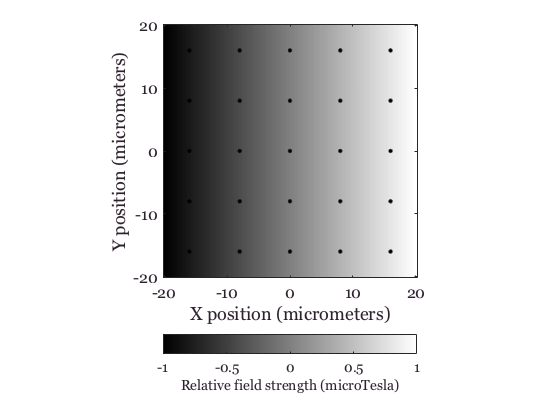

figure(1);
ih = imagesc(x,y,relativeFieldStrengthImg);
colormap(gray(256));
cbh = colorbar('SouthOutside');
set(get(cbh,'Xlabel'),'String','Relative field strength (microTesla)');
axis equal tight xy;
ah = gca;
xlabel('X position (micrometers)');
ylabel('Y position (micrometers)');

% Place some example spin packets in there:
sx = linspace(-voxelSize/2+voxelSize/10, voxelSize/2-voxelSize/10, 5);
sy = linspace(-voxelSize/2+voxelSize/10, voxelSize/2-voxelSize/10, 5);
[spinXLocs,spinYLocs] = meshgrid(sx,sy);
hold on;
spinPoint = zeros(1,numel(spinXLocs));
spinCenter = zeros(1,numel(spinXLocs));
for(ii=1:numel(spinXLocs(:)))
    spinPoint(ii) = plot(spinXLocs(ii), spinYLocs(ii), 'r.','markerSize',12);
	spinCenter(ii) = plot(spinXLocs(ii), spinYLocs(ii), 'k.','markerSize',12);
end
hold off;

% Calculate the relative spin frequency at each spin location. Our gradient
% strengths are expressed as T/cm and are symmetric about the center of the
% voxelSize. To understand the following expression, work through the units:
% (centimeters * T/cm + centimeters * T/cm) * Hz/Tesla + Tesla*Hz/Tesla leaves us with MHz
format long
spinFreq = (spinXLocs(:)*gx+spinYLocs(:)*gy)*gyromagneticRatio + B0*gyromagneticRatio

spinFreq =    1.0e+08 *

   1.277399659360000
   1.277399659360000
   1.277399659360000
   1.277399659360000
   1.277399659360000
   1.277399829680000
   1.277399829680000
   1.277399829680000
   1.277399829680000
   1.277399829680000
   1.277400000000000
   1.277400000000000
   1.277400000000000
   1.277400000000000
   1.277400000000000
   1.277400170320000
   1.277400170320000
   1.277400170320000
   1.277400170320000
   1.277400170320000
   1.277400340640000
   1.277400340640000
   1.277400340640000
   1.277400340640000
   1.277400340640000


format short 

% Note that including the B0 field in this equation simply adds an offset
% to the spin frequency. For most purposes, we usually only care about the
% spin frequency relative to the B0 frequency (i.e., the rotating frame of
% reference), so we can leave that last term off and compute relative
% frequencies:
relativeSpinFreq = (spinXLocs(:)*gx+spinYLocs(:)*gy)*gyromagneticRatio

relativeSpinFreq =   -34.0640
  -34.0640
  -34.0640
  -34.0640
  -34.0640
  -17.0320
  -17.0320
  -17.0320
  -17.0320
  -17.0320


## Question 2

- Speculate on why the relative spin frequency is the most important value to calculate here.

- Do you think the B0 field strength will play a role in the calcualtion of the diffusion tensor?

## Display the relative frequencies, in Hz:

When we first apply an RF pulse, all the spins will all precess in phase. If they are all experienceing the same magnetic field, they will remain in phase. However, if some spins experience a different local field, they will become out of phase with the others. Let's show this with a movie, where the phase will be represented with color. Our timestep is 1 millisecond

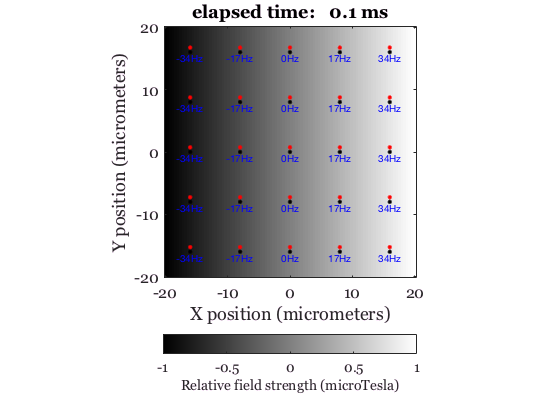

for(ii=1:numel(spinXLocs(:)))
    text(spinXLocs(ii),spinYLocs(ii),sprintf('%0.fHz',relativeSpinFreq(ii)),'color','blue','HorizontalAlignment','center','VerticalAlignment','top');
end

timeStep = .001;

% Initialize the transverse magnitization to reflect a 90 deg RF pulse:
Mxy0 = 2;
curSpinPhase = repmat(0, size(spinCenter));
T2 = 0.10;
t = 0;
nTimeSteps = 100;
for(ti=1:nTimeSteps)
    S = 0;
    for(s=1:numel(spinCenter))
        % Get the position of this spin packet
        sx = get(spinCenter(s),'XData');
        sy = get(spinCenter(s),'YData');
        % Update the current phase
        curSpinPhase(s) = curSpinPhase(s) + 2*pi*gyromagneticRatio * (sx*gx+sy*gy) * timeStep;
        % Do a 180 flip at the TE/2:
        if(ti==round(nTimeSteps/2))
            curSpinPhase(s) = -curSpinPhase(s);
        end
        % The transverse magnitization magnitude decays with the T2:
        %Mxy = Mxy0 + exp(-t/T2) * exp(1i*curSpinPhase(s)); 
        %curMag = abs(Mxy);
        %curPhase = angle(Mxy);
        curMagnitude = Mxy0*exp(-t/T2);
        curPhase = curSpinPhase(s);
        px = sin(curPhase)*curMagnitude;
        py = cos(curPhase)*curMagnitude;
        set(spinPoint(s), 'XData',sx+px, 'YData',sy+py);
        % Summarize the total MR signal for this iteration
        S = S + px^2 + py^2;
    end
    S = sqrt(S)/numel(spinCenter);
    t = t+timeStep;
    set(get(ah,'Title'),'String',sprintf('elapsed time: %5.1f ms',timeStep*t*1000));
    pause(.1);
end

## End